# Polymer temperature dependent properties interpolation

## A) Thermal Conductivity, k(T).

*Interpolates linearly a 1D thermal conductivity point cloud, with a constant temperature tabulation interval TA_0.*

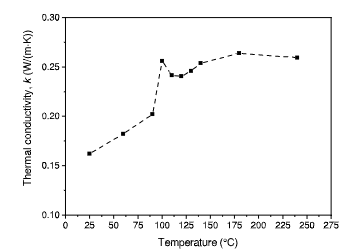

Define tabulated data k(T).

TA_in = 273.15+[24.800, 60.242, 90.364, 100.481, 110.598, 120.485, 129.912, 139.799, 180.497, 239.600];

K_in = [0.161937, 0.182207, 0.202027, 0.255405, 0.241441, 0.240766, 0.245946, 0.253604, 0.264189, 0.259459];

Define the query points to be a finer sampling over the range of x.

TA_0 = 273.15+24.8:5:239.6+273.15;  % tabulation interval of 5

Interpolate the function at the query points and plot the result.

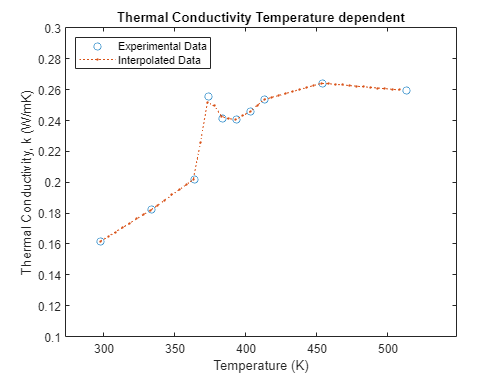

figure
K = interp1(TA_in,K_in,TA_0);
plot(TA_in,K_in,'o',TA_0,K,':.');
xlim([273.15 548.15]);
ylim([0.10 0.30]);
title('Thermal Conductivity Temperature dependent');
xlabel('Temperature (K)')
ylabel('Thermal Conductivity, k (W/mK)')
legend({'Experimental Data','Interpolated Data'},'Location',['NorthWest'])

TA_0

TA_0 =   297.9500  302.9500  307.9500  312.9500  317.9500  322.9500  327.9500  332.9500  337.9500  342.9500  347.9500  352.9500  357.9500  362.9500  367.9500  372.9500  377.9500  382.9500  387.9500  392.9500  397.9500  402.9500  407.9500  412.9500  417.9500  422.9500  427.9500  432.9500  437.9500  442.9500  447.9500  452.9500  457.9500  462.9500  467.9500  472.9500  477.9500  482.9500  487.9500  492.9500  497.9500  502.9500  507.9500


K

K =     0.1619    0.1648    0.1677    0.1705    0.1734    0.1762    0.1791    0.1820    0.1852    0.1885    0.1918    0.1951    0.1984    0.2017    0.2254    0.2518    0.2494    0.2425    0.2412    0.2408    0.2431    0.2459    0.2497    0.2536    0.2549    0.2562    0.2575    0.2588    0.2601    0.2614    0.2627    0.2640    0.2638    0.2634    0.2630    0.2626    0.2622    0.2618    0.2614    0.2610    0.2606    0.2602    0.2598


## B) Specific Heat Capacity, cp(T).

*Interpolates linearly a 1D specific heat capacity point cloud, with a constant temperature tabulation interval TB_0.*

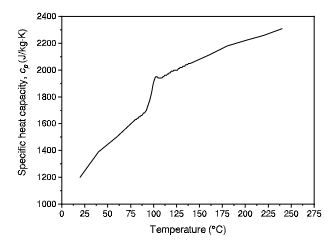

Define tabulated data cp(T).

TB_in = 273.15+[20.212 35.183 40.174 52.141 59.621 79.573 92.288 96.904 98.596 99.79 101.477 103.16 106.618 109.287 119.775 133.621 150.534 164.183 180.109 210.764 240.827];

cp_in = [1199.14 1343.82 1389.78 1452.72 1493.55 1627.97 1692.62 1789.03 1851.88 1896.48 1936.35 1951.21 1941.05 1940.35 1990.31 2028.75 2081.36 2122.51 2178.51 2237.8	2307.91];

Define the query points to be a finer sampling over the range of x.

TB_0 = 273.15+20.212:5:240.827+273.15; % tabulation interval of 5

Interpolates the function at the query points and plots the result.

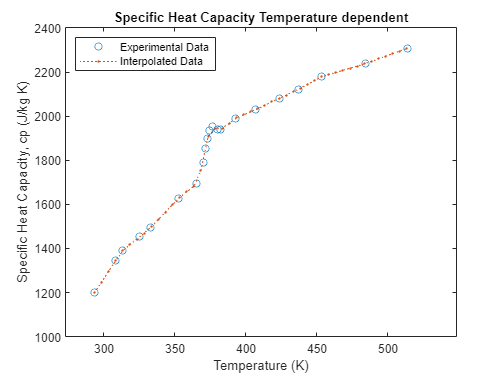

figure
cp = interp1(TB_in,cp_in,TB_0);
plot(TB_in,cp_in,'o',TB_0,cp,':.');
xlim([273.15 275+273.15]);
ylim([1000 2400]);
title('Specific Heat Capacity Temperature dependent');
xlabel('Temperature (K)')
ylabel('Specific Heat Capacity, cp (J/kg K)')
legend({'Experimental Data','Interpolated Data'},'Location',['NorthWest'])

TB_0

TB_0 =   293.3620  298.3620  303.3620  308.3620  313.3620  318.3620  323.3620  328.3620  333.3620  338.3620  343.3620  348.3620  353.3620  358.3620  363.3620  368.3620  373.3620  378.3620  383.3620  388.3620  393.3620  398.3620  403.3620  408.3620  413.3620  418.3620  423.3620  428.3620  433.3620  438.3620  443.3620  448.3620  453.3620  458.3620  463.3620  468.3620  473.3620  478.3620  483.3620  488.3620  493.3620  498.3620  503.3620  508.3620  513.3620


cp

cp = 	1.0e+03 *

    1.1991    1.2475    1.2958    1.3441    1.3900    1.4163    1.4426    1.4695    1.4975    1.5312    1.5649    1.5986    1.6312    1.6566    1.6821    1.7537    1.9065    1.9452    1.9448    1.9686    1.9915    2.0054    2.0193    2.0337    2.0493    2.0648    2.0804    2.0955    2.1105    2.1261    2.1437    2.1613    2.1787    2.1884    2.1981    2.2077    2.2174    2.2271    2.2367    2.2482    2.2598    2.2715    2.2832    2.2948    2.3065


## C) Specific Enthalpy, h(T).

*Cumulative trapezoidal numerical integration of the interpolated scpecific heat capacity cp, getting the temperature dependent specific enthalpy H.*

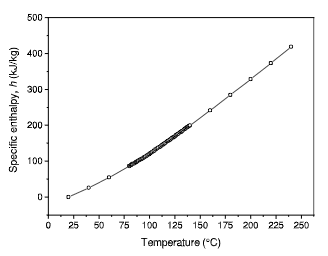

Origin of coordinates is changed so that the inf. limit of integration coincides with T=0. 

TC_ref = TB_0-293.3620;

Cumulative trapezoidal numerical integration of cp, getting h.

h = cumtrapz(TC_ref,cp);

Plots temperature dependent Specific Enthalpy h(T).

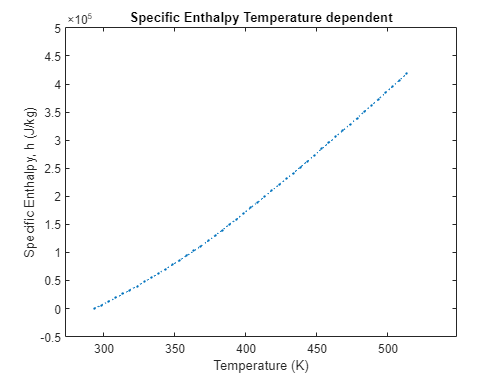

figure
plot(TB_0,h,':.');
xlim([273.15 275+273.15]);
ylim([-50000 500000]);
title('Specific Enthalpy Temperature dependent');
xlabel('Temperature (K)')
ylabel('Specific Enthalpy, h (J/kg)')

TB_0

TB_0 =   293.3620  298.3620  303.3620  308.3620  313.3620  318.3620  323.3620  328.3620  333.3620  338.3620  343.3620  348.3620  353.3620  358.3620  363.3620  368.3620  373.3620  378.3620  383.3620  388.3620  393.3620  398.3620  403.3620  408.3620  413.3620  418.3620  423.3620  428.3620  433.3620  438.3620  443.3620  448.3620  453.3620  458.3620  463.3620  468.3620  473.3620  478.3620  483.3620  488.3620  493.3620  498.3620  503.3620  508.3620  513.3620


h

h = 	1.0e+05 *

         0    0.0612    0.1247    0.1907    0.2591    0.3293    0.4007    0.4735    0.5477    0.6234    0.7008    0.7799    0.8607    0.9428    1.0263    1.1122    1.2037    1.3000    1.3973    1.4951    1.5941    1.6940    1.7946    1.8960    1.9980    2.1009    2.2045    2.3089    2.4141    2.5200    2.6267    2.7343    2.8428    2.9520    3.0617    3.1718    3.2825    3.3936    3.5052    3.6173    3.7300    3.8433    3.9571    4.0716    4.1866


## D) Density**,** $\rho$**(T, P). Eq. of State.**

*Interpolates linearly a 2D density point cloud, with a constant temperature and pressure tabulation interval TD_0 and PD_0.*

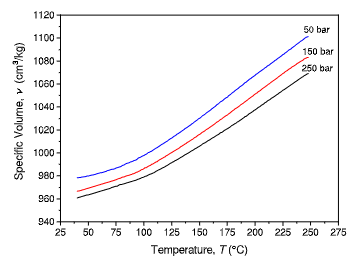

Define tabulated data $\rho
$(T,P).

Same number of points for each pressure curve:

%curva 1: 50 bar
TD1_in = 273.15+[40.250 56.320 66.377 75.611 82.177 94.693 105.359 114.999 135.097 150.273 189.848 199.281 226.145 241.525 246.857];

rho1_in = [978.211 981.033 983.819 987.002 989.588 994.760 1000.927 1006.895 1020.224 1030.369 1060.210 1067.172 1086.071 1097.609 1100.792];

PD1_in = [50 50 50 50 50 50 50 50 50 50 50 50 50 50 50];

%curva 2: 150 bar
TD2_in = 273.15+[40.125 48.335 59.212 69.678 80.555 95.329 103.944 114.406 153.170 171.217 195.825 211.615 229.251 239.710 247.505];

rho2_in = [966.511 968.700 971.684 974.668 978.248 983.421 988.195 993.765 1018.035 1030.369 1047.876 1059.414 1072.146 1078.909 1083.286];

PD2_in = [150 150 150 150 150 150 150 150 150 150 150 150 150 150 150];

%curva 3: 250 bar
TD3_in = 273.15+[40.137 45.677 53.476 61.685 72.151 87.748 107.037 130.011 149.702 176.776 184.000 195.439 218.203 239.327 247.120];

rho3_in = [960.145 962.135 964.323 966.511 969.893 974.469 981.431 993.964 1005.502 1022.014 1026.653 1034.547 1049.666 1063.79 1068.963];

PD3_in = [250 250 250 250 250 250 250 250 250 250 250 250 250 250 250];

Each of the variables is concatenated into a single array

TD_in=[TD1_in TD2_in TD3_in];
PD_in=[PD1_in PD2_in PD3_in];
rho_in=[rho1_in rho2_in rho3_in];

Point cloud plot:

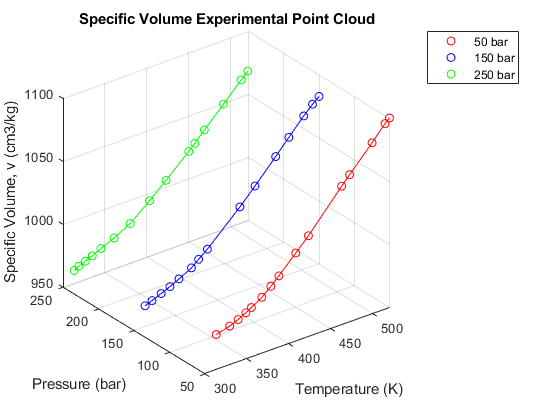

t.TileSpacing = 'tight';
t.Padding='tight';
scatter3(TD1_in,PD1_in,rho1_in,'r')
line(TD1_in,PD1_in,rho1_in, 'Color', 'r')
hold on
scatter3(TD2_in,PD2_in,rho2_in,'b')
line(TD2_in,PD2_in,rho2_in, 'Color', 'b')
hold on
scatter3(TD3_in,PD3_in,rho3_in,'g')
line(TD3_in,PD3_in,rho3_in, 'Color', 'g')
hold off
title('Specific Volume Experimental Point Cloud')
xlabel('Temperature (K)')
ylabel('Pressure (bar)')
zlabel('Specific Volume, v (cm3/kg)')
legend({'50 bar','','150 bar','','250 bar',''})

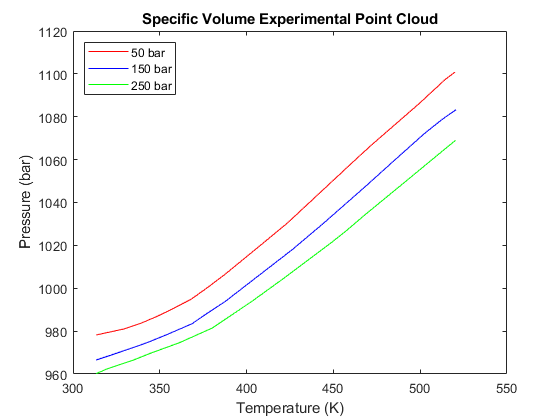

plot(TD1_in,rho1_in,'r')
hold on
plot(TD2_in,rho2_in,'b')
hold on
plot(TD3_in,rho3_in,'g')
hold off
title('Specific Volume Experimental Point Cloud')
xlabel('Temperature (K)')
ylabel('Pressure (bar)')
legend({'50 bar','150 bar','250 bar'}, 'Location', 'NorthWest')

Interpolation of data and its plot:

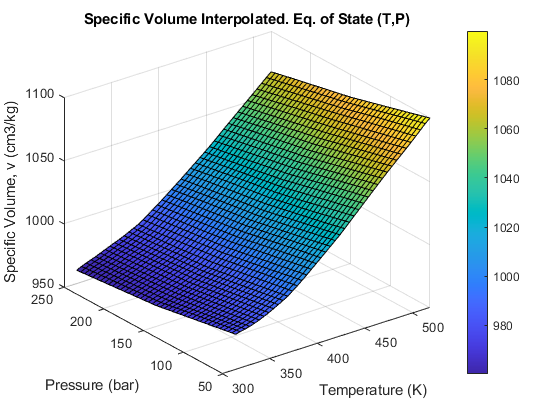

[TD_0,PD_0]=meshgrid(273.15+40.250:5:247.505+273.15, 50:5:250); % The mesh starts in 40.250 and not in 40.125 due to avoid extrapolation.  % tabulation interval of 5

rho_v = griddata(TD_in,PD_in,rho_in,TD_0,PD_0);

figure
surf(TD_0,PD_0,rho_v)
title('Specific Volume Interpolated. Eq. of State (T,P)')
xlabel('Temperature (K)')
ylabel('Pressure (bar)')
zlabel('Specific Volume, v (cm3/kg)')
colorbar

Por último, se obtiene la densidad como la inversa del volumen específico y se convierte a unidades del S.I (kg/m3).

rho = 1./(rho_v*1e-06);

TD_0(1,:)

ans =   313.4000  318.4000  323.4000  328.4000  333.4000  338.4000  343.4000  348.4000  353.4000  358.4000  363.4000  368.4000  373.4000  378.4000  383.4000  388.4000  393.4000  398.4000  403.4000  408.4000  413.4000  418.4000  423.4000  428.4000  433.4000  438.4000  443.4000  448.4000  453.4000  458.4000  463.4000  468.4000  473.4000  478.4000  483.4000  488.4000  493.4000  498.4000  503.4000  508.4000  513.4000  518.4000


PD_0(:,1)

ans =     50
    55
    60
    65
    70
    75
    80
    85
    90
    95


rho

rho = 	1.0e+03 *

    1.0223    1.0214    1.0204    1.0195    1.0182    1.0168    1.0151    1.0133    1.0113    1.0092    1.0071    1.0049    1.0020    0.9991    0.9961    0.9930    0.9897    0.9865    0.9833    0.9801    0.9769    0.9737    0.9705    0.9670    0.9635    0.9600    0.9565    0.9531    0.9497    0.9463    0.9429    0.9397    0.9365    0.9334    0.9303    0.9273    0.9243    0.9213    0.9181    0.9150    0.9119    0.9092
    1.0229    1.0219    1.0210    1.0201    1.0187    1.0173    1.0156    1.0138    1.0118    1.0098    1.0077    1.0055    1.0026    0.9997    0.9967    0.9936    0.9904    0.9871    0.9839    0.9807    0.9776    0.9744    0.9712    0.9677    0.9642    0.9607    0.9573    0.9538    0.9504    0.9470    0.9437    0.9404    0.9372    0.9341    0.9310    0.9280    0.9250    0.9220    0.9188    0.9157    0.9125    0.9100
    1.0235    1.0225    1.0216    1.0207    1.0193    1.0178    1.0161    1.0144    1.0124    1.0104    1.0083    1.0061    1.0032    1.0003